## [Additive Manufacturing](https://apmonitor.com/pds/index.php/Main/AdditiveManufacturing)'

Additive manufacturing is the process of building from a computer controlled 3-dimensional printer. The material can be polymer (plastic), ceramic, metallic powder, liquid, or any material that is joined together through deposition, solidification, or fusion. It speeds the development of prototypes by precisely converting a computer aided design (CAD) drawing into a physical device. Additive manufacturing can be either a prototype or scaled up to full product production, but typically for applications that require customization or with low production volumes.

**Background:** A [**3D print data set of additive manufacturing test conditions**](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is available for Polylactic Acid (PLA) and Acrylonitrile Butadiene Styrene (ABS). PLA can print at lower temperatures of 180°C compared to 250°C for ABS. PLA is more brittle than ABS and is not typically suitable for high strength applications. The data was collected by researchers in the Mechanical Engineering department at Selçuk Üniversitesi on a Ultimaker S5 3D printer. The study focused on how the parameters in a specific 3D printer affects the print quality, accuracy and final part strength. This work is based on the settings and PLA or ABS filaments. Material and strength tests were carried out on a Sincotec GMBH tester capable of pulling 20 kN.

Nine parameters were adjusted for the Ultimaker S5 3D printer.

- Layer Height (mm)

- Wall Thickness (mm)

- Infill Density (%)

- Infill Pattern (Honeycomb or Grid)

- Nozzle Temperature (ºC)

- Bed Temperature (ºC)

- Print Speed (mm/s)

- Material (PLA or ABS)

- Fan Speed (%)

After the part was manufactured, three parameters were measured for each product.

- Roughness (µm)

- Tension Strength (MPa)

- Elongation (%)

The labeled data is a combination of PLA and ABS material, print patterns, and conditions with 66 samples from a first repository and 50 samples from a second repository. The [**combined set**](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is 70 samples with the duplicates removed and one outlier added. The label associated with each filament is *pla* or *abs*. The print pattern is *grid* or *honeycomb*. [**One-hot encoding**](https://en.wikipedia.org/wiki/One-hot) translates character labels into a binary representation (0 or 1) for classification.

 [**Additive Manufacturing Data**](https://apmonitor.com/pds/uploads/Main/manufacturing.txt)

## Part 1: Data Visualization and Cleansing

Generate summary statistics with a profiling report to [**statistically characterize the data**](https://apmonitor.com/pds/index.php/Main/StatisticsMath). Use box plots to identify the one outlier in the data. Remove the row that contains the outlier from the data set. Generate a pair plot and correlation matrix. What factors are highly correlated to *Material (PLA or ABS)* and *Tension Strength (MPa)*?

%Clear proceeding data 
clear;
%Load data from URL 
url = "https://apmonitor.com/pds/uploads/Main/manufacturing.txt";
data = readtable(url);

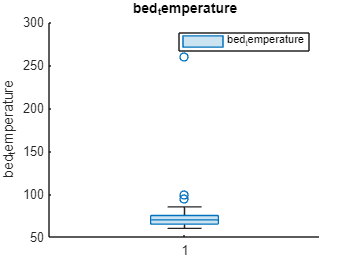

% Create boxchart of data.bed_temperature
h2 = boxchart(data.bed_temperature,"DisplayName","bed_temperature");

% Add ylabel, title, and legend
ylabel("bed_temperature")
title("bed_temperature")
legend

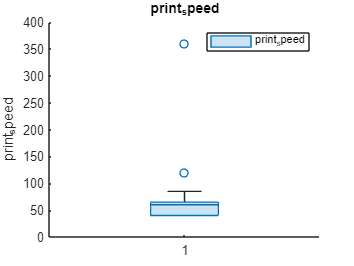

% Create boxchart of data.print_speed
h = boxchart(data.print_speed,"DisplayName","print_speed");

% Add ylabel, title, and legend
ylabel("print_speed")
title("print_speed")
legend


% Fill outliers
[cleaned, TFrm] = rmoutliers(data.bed_temperature,"percentiles",[5 95]);

data_clean = data(~TFrm,:);

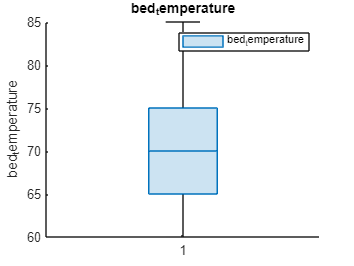

% Create boxchart of data_clean.bed_temperature
h3 = boxchart(data_clean.bed_temperature,"DisplayName","bed_temperature");

% Add ylabel, title, and legend
ylabel("bed_temperature")
title("bed_temperature")
legend